# The Effects of Quarantine Rates on Peak Infections of Super Spreading Diseases

Sofia Ramos, Derek Martielli

## Question

## What percent of infected individuals need to quarantine to cut the peak of super spreading diseases by 50%? 

This is a moderately general rhetorical question. While we are aiming to find specific values, the scenario we are constructing does not directly reflect any one disease. We are not able to directly affect how many people quarantine but our results can help inform personal decisions. Our modeling question is important as it pinpoints the effectiveness of quarantining in reducing the number of infections of super spreading diseases. Understanding how to prevent the spread of a disease is crucial as diseases negatively impact the health of individuals. 

Much of our research was on modeling COVID-19. This is because COVID-19 is a disease that famously spreads through super spreading events (Althouse, 2020). None of the research directly answers our question, but it does provide a framework for modeling and results we can expect.

## Methodology/Model

Our model is a stochastic agent based SEIQR model. An agent can be susceptible, exposed, infected, quarantined, or recovered. Unlike a typical agent based model though, new infections are calculated with a stochastic process. Our model does not use a social graph for infection, instead stochastically calculating the amount of new people to infect and randomly distributing that number into the population. This approach allows unique disease spread distributions while keeping quarantining simple to model. 

Fig 1. Tenchi Diagram

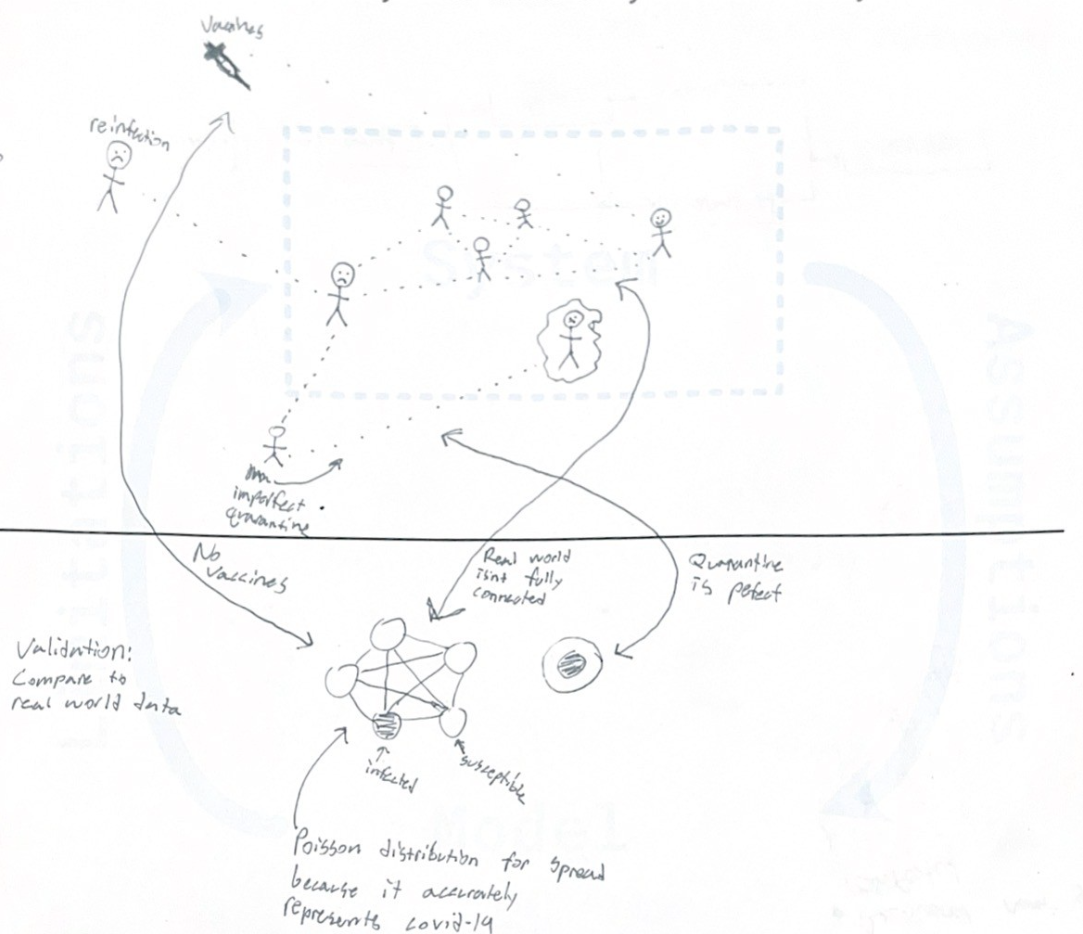

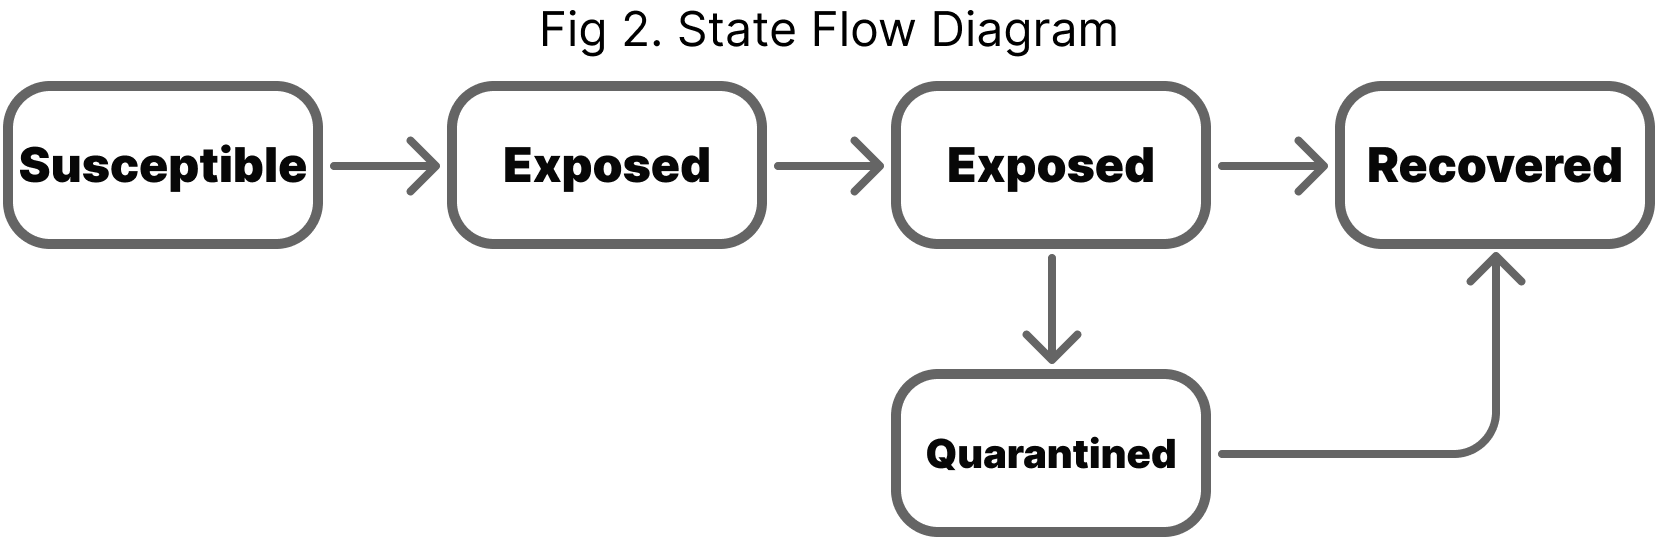

Fig 1. is a Tenchi Diagram of how our SEIQR model compares to the natural world. 

Fig 2 is a state flow diagram that demonstrates how super-spreading diseases transmit to individuals.

Our model makes the assumptions that individuals aren’t vaccinated, there’s connections within the population and quarantine is correctly implemented. Some limitations that these assumptions impose is the model being unable to produce an outcome of how effective quarantine is with the addition of vaccinations and a result of not following quarantine procedures correctly. We’re able to bypass these limitations by rationalizing that vaccinations are typically produced significantly after a disease is introduced, limiting our data. When considering following quarantine procedures, we’re able to model accuracy by expecting that all individuals properly follow guidelines. 

#### Model Breakdown

The model takes 6 total parameters:

recovery_rate = 0.25;                            % Chance to recover each timestep
n_population = 1000;                              % Population size
quarantine_percent = 0.5;                      % Percent of infected people who quarantine each timestep
R0 = 2.6;                                                % Disease reproduction number
k = 0.16;                                                 % Disease dispersion
Iv1 = zeros(n_population, 1); Iv1(1) = 1;  % Initial infection vector with one person infected
Timesteps = 100;                                    %Timesteps to run

Besides quarantine percent, all of these values will be the same throughout the entire paper. Many of the parameters were set using real world data from COVID-19. We use COVID-19 data because it is well documented and a prime example of a disease that spreads through super spreading events (Althouse, 2020). The recovery rate of 0.25 reflects COVID-19 recovery time of 4 days (Davies, Nicholas G et al, 2020). We use a population size of 1000 as it is the largest population we can reasonably simulate. Quarantine percent represents an infected individual's chance to enter quarantine each timestep. Once in quaranting the agaent will remain in quarantine until recovered. Here the parameter is set to 0.5 or 50% but it is swept in our final simulation. For the negative binomial disease spread we use mean (R₀) of 2.6 and a dispersion parameter (k) of 0.16. These values are from the (Althouse, 2020) paper and are chosen to reflect COVID-19's spread. The vector Iv1 represents the initial infection state of the model. Right now it is set so that only person no.1 is infected. We run each simulation for 100 timesteps as all runs end well before this time is reached.

The model starts by running some setup:  

In addition to making matrices to hold data, this is where the negative binomial distribution is generated.

   % Generate NB distribution for use in the model
   R0 = 2.6;  % disease reproduction number
   k = 0.16;   % disease dispersion
   r = k;
   p = (k)/(R0+k); %WHAT IS P?????????????????????????????
   pd_sse = makedist('NegativeBinomial', 'r', r, 'p', p);  % Negative Binomial distribution


Visualized, the distribution looks like this:

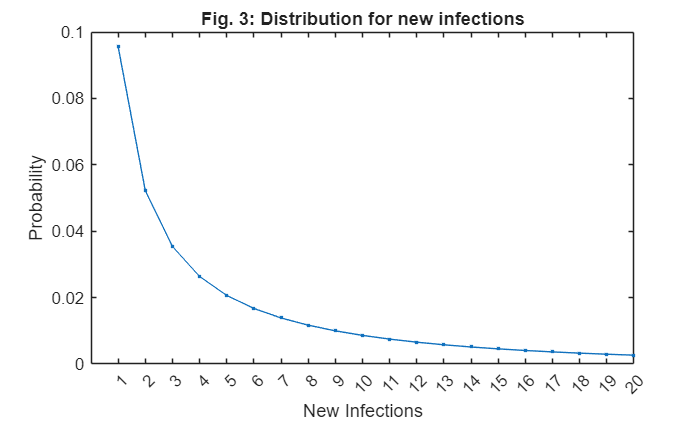

semilogy(1:20, pdf(pd_sse, 1:20), '.-', 'DisplayName', 'Negative '); xticks([1:20]);set(gca, 'YScale', 'linear');xlabel("New Infections");ylabel("Probability");title("Fig. 3: Distribution for new infections");

Fig. 3 shows the probability curve for how many people an infected person will infect. Most often an infected individual will infect 0 new people during the timestep. This distribution extends out very far though which allows for the possibility of a super spreading event. With the setup done the action function can start running.

Step 1 of the action is to calculate the amount of new infections:

While our model is agent based we primarily use the amount of new infections for calculating disease spread.

Step 2 is to calculate vectors for updating all the agents states:

$v\_\mathrm{exposed}\_\mathrm{to}\_\mathrm{infected}$ is a vector that represents what people can move from being exposed to infected. It is set so that people exposed have a 25% chance to move to being infected. This reflects the real world incubation time of covid being ~4 days (Davies, Nicholas G et al, 2020). $v\_\textrm{recover}$ is a vector that shows which people can become recovered. The chance for recovery is defined before the model is run. $v\_\textrm{quarantine}$ is a vector that represents which people can go from infected to quarantined. This is where the $\textrm{quarantine}\_\textrm{percent}$ parameter is used. $v\_\textrm{exposed}$ is the vector used to represent who gets exposed to the infection. Which specific agents get exposed is random but the amount of exposures (new infections) should be the amount calculated in step 1.

Step 3 is to update all the agents states:

The additional logic is required to ensure the model properly updates.

#### Verification

With the model built we can run some verification. The three things we will check are:

- Agents only have 1 state at a time

- The susceptible population never goes up

- Recovered people never get reinfected

We can check that agents don't have multiple states by running the model and comparing the state histories. At every timestep the susceptible, exposed, infected, quarantined, and recovered counts should all add up to the total population.

%Run a demo simulation using our earlier parameters
[Sh, Ih, Rh,Qh,Eh] = simulate_absir(Iv1, Timesteps, recovery_rate, quarantine_percent);

% Make a vector where each element is the sum of the states at a timestep
sum_states = sum((Sh+Ih+Rh+Eh+Qh))

sum_states =         1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000


assert(all(sum_states == 1000));disp("Assertion passed, the sum of the states is 1000 for every timestep");

Assertion passed, the sum of the states is 1000 for every timestep


To make sure this is not a fluke we can run the model 200 times and check again.

% Make a matrix to store the data
All_sums = zeros(200,100);

% Run simulation 200 times
for i = 1 : 200
    [Sh, Ih, Rh,Qh,Eh] = simulate_absir(Iv1, Timesteps, recovery_rate, quarantine_percent);
    All_sums(i,:) = sum((Sh+Ih+Rh+Eh+Qh)); % Record the state sums as a row in the All_sums matrix
end

%Check that every timestep of every simulation adds up to 1000
assert(all((All_sums == 1000),"all"));disp("Assertion passed, the sum of the states is always 1000");

Assertion passed, the sum of the states is always 1000


Next we can check that the susceptible population doesn't go up. Again we'll use 200 simulations to ensure accuracy.

% Run simulation 200 times
for i = 1 : 200
    [Sh, Ih, Rh,Qh,Eh] = simulate_absir(Iv1, Timesteps, recovery_rate, quarantine_percent);
    
    % Convert the susceptible history into a vector
    Sh = sum(Sh);

    % Check that the amount of susceptible people does not go up between steps
    assert(all((diff(Sh) <=0 ),"all"));
end

The assert statement passed for all 200 simulations! We can now check to see if recovered individuals ever get reinfected. Similar to the last verification we will run 200 simulations checking every time step.

for i = 1 : 200
    [Sh, Ih, Rh,Qh,Eh] = simulate_absir(Iv1, Timesteps, recovery_rate, quarantine_percent);
    
    % Check that no one ever gets "unrecovered"
    assert(all((diff(Rh,1,2) >=0 ),"all"));
end

With this verification complete we can move to validation.

#### Validation

We validated our model by comparing some of our results with real infection graphs from Covid-19 that show similarities in infection peaks. Often, there isn’t a singular sharp peak but a cluster of close together peaks. In the article, *The impact of quarantine on Covid-19 infections, *graphs of different cities in Chile demonstrate that the mean peak of Covid-19 is severely lowered after implementing quarantine. Looking at our results, we can see similar behaviors as the mean peak infection is cut by 50% when a large portion of the population quarantines after becoming infected. Another way of validating our results is by comparing our outcomes to see if we get similar results to some of the papers. In the article, *A rapid review of quarantine and/or other public health measures to control COVID‐19, data* showed that quarantining could eliminate 44-96% cases of Covid-19. We're able to see if our model is accurate by having very high quarantine rates resulting in a minimalized peak of infections.

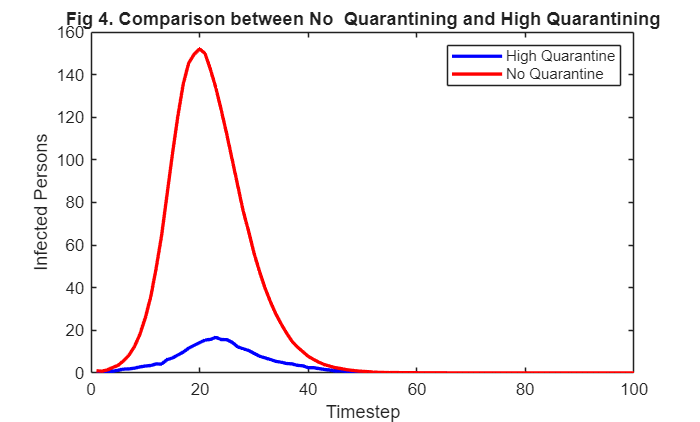

% Set up parameter values
quarantine_percent = 0.8;
quarantine_percent_none = 0;

% One initial infected person
Iv1 = zeros(n_population, 1); Iv1(1) = 1;

% Set up simulation parameters
n_realizations = 100;

% Generate the sample of results
I_ensemble = zeros(Timesteps, n_realizations);
I_ensemble_none = zeros(Timesteps,n_realizations);

% Run simulation
for i = 1 : n_realizations
   [~, Ih, ~,~,~] = simulate_absir(Iv1, Timesteps, recovery_rate, quarantine_percent);
   I_ensemble(:, i) = sum(Ih, 1);
   [~, Ih, ~,~,~] = simulate_absir(Iv1, Timesteps, recovery_rate, quarantine_percent_none);
   I_ensemble_none(:, i) = sum(Ih, 1);
end

% Make Graph
plot(mean(I_ensemble, 2), 'b', 'LineWidth', 2); hold on
plot(mean(I_ensemble_none,2), 'r','LineWidth',2);
legend('High Quarantine','No Quarantine');
xlabel('Timestep')
ylabel('Infected Persons')
title('Fig 4. Comparison between No  Quarantining and High Quarantining'); hold off

         Fig. 5 Covid-19 model with and without quarantine (Marshall, 2021).

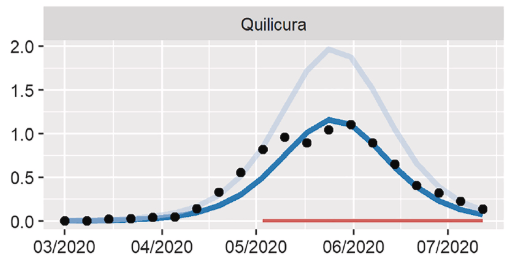

Figures 4 & 5 show our model producing similar behavior to real world data and other models. We also see that very high quarantine percentages are able to cut peak infections by the expected amount.

## Results

We will perform a parameter sweep over quarantine percent, using peak infections as our metric. Doing this will allow us to directly answer our question. To account for the stochasticity of the model, we run each quarantine percent 100 times and take the average.

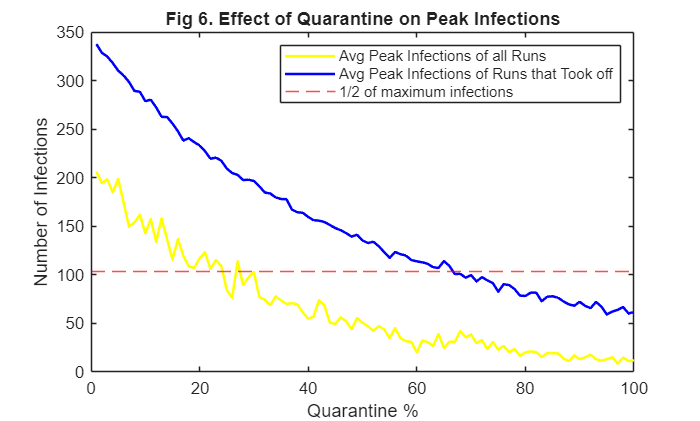

% Re-set parameters
recovery_rate = 0.25;
n_population = 1000;

% One initial infected person
Iv1 = zeros(n_population, 1); Iv1(1) = 1;

% Set up simulation parameters
timestep = 100;
n_realizations = 100;
I_ensemble = zeros(n_realizations,1);
Peak_history = zeros(100,1);
Peak_takeoff_history = zeros(100,1);

% Run the final simulation
   for i = 1:100
      quarantine_percent = i/100; % percent varies
    for k = 1:n_realizations
        [Sh, Ih, Rh,Qh,Eh] = simulate_absir(Iv1, timestep, recovery_rate, quarantine_percent);
       I_ensemble(k,1) = max(sum(Ih));
    end
      I_takeoff_idx = I_ensemble>3;
      I_takeoff = I_ensemble(I_takeoff_idx);
      peak_all  = mean(I_ensemble);
      Peak_history(i) = peak_all;
      Peak_takeoff_history(i) = mean(I_takeoff);
   end

% Graph Results
figure
plot(Peak_history,'LineWidth',1.5,"Color", 'yellow'); hold on
plot(Peak_takeoff_history,'LineWidth',1.5,"Color", 'blue');
yline(max(Peak_history)/2,'--', "Color", 'red')
xlabel('Quarantine %')
ylabel('Number of Infections')
legend("Avg Peak Infections of all Runs","Avg Peak Infections of Runs that Took off","1/2 of maximum infections")
title('Fig 6. Effect of Quarantine on Peak Infections'); hold off

Fig. 6 shows the results of different quarantine percentages on peak infections.

We found that roughly 65% of infected people need to quarantine per timestep to cut peak infections of super spreading diseases in half. The results when looking at all runs (including those that did not take off) suggest that there may be a lower quarantine percentage required for diseases that have yet to take off. Further research may look at how quarantining rates affect the chance of a disease taking off. 

## Ai Statement:

No AI was used in the making of this project.